% Plot of Robot path (theoretical and measured)

clear

load('matlab.mat')

syms t r 
assume(t,'real');
assume(t,'positive');

%%% Theoretical

ri = (0.3960*cos(2.65*(0.1*t+1.4)));
rj = (-0.99*sin(0.1*t+1.4));
rk = 0*t;
r = [ri,rj,rk];
drdt = diff(r,t);

%calculating unit tangent vector
T_hat = drdt/norm(drdt);
dT_hatdt = diff(T_hat,t);

%turning vector components of t_hat into x and y functions (MATLAB)
t_hat_x = matlabFunction(T_hat(1));
t_hat_y = matlabFunction(T_hat(2));

%calculating unit normal vector
N_hat = dT_hatdt/norm(dT_hatdt);

%turning vector components of n_hat into x and y functions (MATLAB)
n_hat_x = matlabFunction(N_hat(1));
n_hat_y = matlabFunction(N_hat(2));

T_hat_matlab = matlabFunction(T_hat);
ri_quiv = matlabFunction(ri);
rj_quiv = matlabFunction(rj);

%define time
t = 0:8:32;

%defines the functions in terms of x and y coordinates
x = ri_quiv(t);
y = rj_quiv(t);
u = t_hat_x(t);
v = t_hat_y(t);
i = n_hat_x(t);
o = n_hat_y(t);

%%% Measured

%define time
t_measured = encoder_data(:,1);

% calculate measured ri and rj
ri_measured = zeros(196,1);
rj_measured = zeros(196,1);

for num = 1:length(encoder_data(:,1))
    ri_measured(num) = (0.3960*cos(2.65*(0.1*t_measured(num)+1.4)));
    rj_measured(num) = (-0.99*sin(0.1*t_measured(num)+1.4));
end   

rk_measured = 0*t_measured;
r_measured = [ri_measured,rj_measured,rk_measured];
drdt_measured = r_measured./t_measured;

%calculating unit tangent vector
T_hat_measured = drdt_measured/norm(drdt_measured);
dT_hatdt_measured = T_hat_measured./t_measured;

%turning vector components of t_hat into x and y functions (MATLAB)
t_hat_x_measured = T_hat_measured(:,1);
t_hat_y_measured = T_hat_measured(:,2);

%calculating unit normal vector
N_hat_measured = dT_hatdt_measured/norm(dT_hatdt_measured);

%turning vector components of n_hat into x and y functions (MATLAB)
n_hat_x_measured = N_hat_measured(:,1);
n_hat_y_measured = N_hat_measured(:,2);

%defines the functions in terms of x and y coordinates
x_measured = ri_measured;
y_measured = rj_measured;
u_measured = t_hat_x_measured;
v_measured = t_hat_y_measured;
i_measured = n_hat_x_measured;
o_measured = n_hat_y_measured;

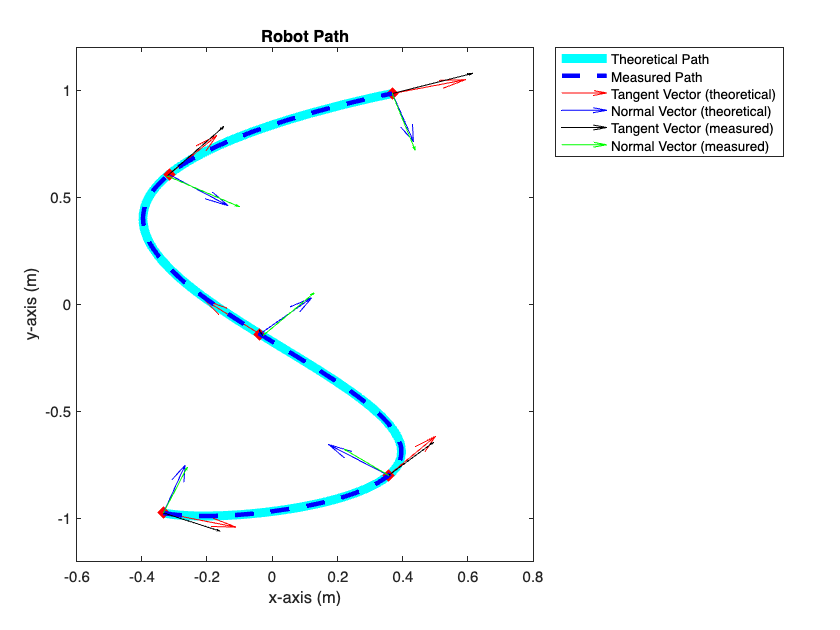

%%% PLOT

figure("Name","Robot Path")
bod_curve = fplot(ri,rj,[0 32],'-c','LineWidth',6);
hold on;
plot(x,y,'xr',LineWidth=6)
unit_tan_graph = quiver(x,y,u*0.25,v*0.25,'-r','LineWidth',0.1);
unit_norm_graph = quiver(x,y,i*0.25,o*0.25,'-b','LineWidth',0.1);
set(unit_tan_graph,'AutoScale','on', 'AutoScaleFactor',0.25)
set(unit_norm_graph,'AutoScale','on', 'AutoScaleFactor',0.25)
xlim([-0.6 0.8])
ylim([-1.2 1.2])
xlabel("x-axis (m)")
ylabel("y-axis (m)")
title("Robot Path")
bod_curve_measured = plot(ri_measured,rj_measured,'--b','LineWidth',3);
hold on;
unit_tan_graph_measured = quiver(x_measured(1),y_measured(1),u_measured(1)*-0.6,v_measured(1)*0.1,'-k','LineWidth',0.1);
unit_norm_graph_measured = quiver(x_measured(1),y_measured(1),i_measured(1)*-0.25,o_measured(1)*-0.25,'-g','LineWidth',0.1);
unit_tan_graph_measured = quiver(x_measured(50),y_measured(50),u_measured(50)*2*10e3,v_measured(50)*-10e3,'-k','LineWidth',0.1);
unit_norm_graph_measured = quiver(x_measured(50),y_measured(50),i_measured(50)*-2.5*10e7,o_measured(50)*-10e7,'-g','LineWidth',0.1);
set(unit_tan_graph_measured,'AutoScale','on', 'AutoScaleFactor',0.5)
set(unit_norm_graph_measured,'AutoScale','on', 'AutoScaleFactor',1)
unit_tan_graph_measured = quiver(x_measured(106),y_measured(106),u_measured(106)*2*10e3,v_measured(106)*-10e3,'-k','LineWidth',0.1);
unit_norm_graph_measured = quiver(x_measured(106),y_measured(106),i_measured(106)*-2*10e9,o_measured(106)*5*-10e8,'-g','LineWidth',0.1);
set(unit_tan_graph_measured,'AutoScale','on', 'AutoScaleFactor',1)
set(unit_norm_graph_measured,'AutoScale','on', 'AutoScaleFactor',0.7)
unit_tan_graph_measured = quiver(x_measured(152),y_measured(152),u_measured(152)*-1.4*10e3,v_measured(152)*10e3,'-k','LineWidth',0.1);
unit_norm_graph_measured = quiver(x_measured(152),y_measured(152),i_measured(152)*-2*10e9,o_measured(152)*7*-10e8,'-g','LineWidth',0.1);
set(unit_tan_graph_measured,'AutoScale','on', 'AutoScaleFactor',3)
set(unit_norm_graph_measured,'AutoScale','on', 'AutoScaleFactor',0.2)
unit_tan_graph_measured = quiver(x_measured(196),y_measured(196),u_measured(196)*7*10e3,v_measured(196)*10e3,'-k','LineWidth',0.1);
unit_norm_graph_measured = quiver(x_measured(196),y_measured(196),i_measured(196)*10e9,o_measured(196)*14*-10e8,'-g','LineWidth',0.1);
set(unit_tan_graph_measured,'AutoScale','on', 'AutoScaleFactor',1)
set(unit_norm_graph_measured,'AutoScale','on', 'AutoScaleFactor',0.2)
legend([bod_curve, bod_curve_measured, unit_tan_graph, unit_norm_graph, unit_tan_graph_measured,unit_norm_graph_measured], ...
    ["Theoretical Path", "Measured Path", "Tangent Vector (theoretical)","Normal Vector (theoretical)", "Tangent Vector (measured)","Normal Vector (measured)"],'Location','northeastoutside')
hold off;